clc; clear

if bdIsLoaded('Flightsim_aircraft')
    set_param('Flightsim_aircraft', 'SimulationCommand', 'stop');
end


ac = Aircraft();
ac.set_reference_point([0 0 0]);


%% Reference Definition

NOSE_REF_CG = [4.88; 0.00; 0.00];

tank_1_nose_ref = [4.00; 0.00; 0.00];
tank_2_nose_ref = [5.50; 0.00; 0.00];

engine_nose_ref = [6.00; 0.00; 0.00];

wing_ac_nose_ref = [4.20; 0.00; 0.00];

cg_to_tank_1 = tank_1_nose_ref - NOSE_REF_CG;
cg_to_tank_2 = tank_2_nose_ref - NOSE_REF_CG;

cg_to_engine = engine_nose_ref - NOSE_REF_CG;

cg_to_wing_ac = wing_ac_nose_ref - NOSE_REF_CG;

%% Mass Properties

ac.mass.set_mass_properties(9300,55800,63100,118000, 0, 0,0,[0 0 0]);

ac.mass.add_fuel_tank(cg_to_tank_1.', 3000, 'distributed');
ac.mass.add_fuel_tank(cg_to_tank_2.', 1500, 'distributed');

ac.mass.set_fuel_mass(2400);

%% Geometry

ac.geometry.wing_area = 27.87;
ac.geometry.wing_span = 9.14;
ac.geometry.mean_aerodynamic_chord = 3.45;

ac.geometry.ref_point = cg_to_wing_ac.';


%% Aerodynamics

ac.set_aerodynamics(CoefficientAerodynamics(@F16Lookup));

%% Control Surfaces

cfg = ac.get_configurator();

cfg.add_control_surface( ...
    'name','aileron', ...
    'surface_type','aileron', ...
    'classification','primary', ...
    'axis',[1 0 0], ...
    'max_deflection',deg2rad(20), ...
    'min_deflection',deg2rad(-20), ...
    'dCl',0.05, ...
    'dCm',0, ...
    'dCn',0);

cfg.add_control_surface( ...
    'name','elevator', ...
    'surface_type','elevator', ...
    'classification','primary', ...
    'axis',[0 1 0], ...
    'max_deflection',deg2rad(25), ...
    'min_deflection',deg2rad(-25), ...
    'dCl',0, ...
    'dCm',0, ...
    'dCn',0);

cfg.add_control_surface( ...
    'name','rudder', ...
    'surface_type','rudder', ...
    'classification','primary', ...
    'axis',[0 0 1], ...
    'max_deflection',deg2rad(30), ...
    'min_deflection',deg2rad(-30), ...
    'dCl',0, ...
    'dCm',0, ...
    'dCn',-0.08);

%% Propulsion

cfg.add_propulsive_element( ...
    'name','F100_PW_229', ...
    'element_type','turbofan_afterburning', ...
    'max_output',128992, ...
    'position',cg_to_engine.', ...
    'direction',[1 0 0], ...
    'fuel_rate',2.5, ...
    'thrust_model',@(thr,M,alt,V,rho) ...
    F100ThrustModel(thr, M, alt, V, rho, 128992));

%% Control Vector

n_cs = numel(ac.control_surfaces);
n_pe = numel(ac.propulsive_elements);

n_total = n_cs + n_pe;

%% Mission Segments

segments = struct('type',{}, 'altitude',{},'mach',{}, 'mach_end',{},'gamma',{}, 'gamma_end',{}, 'h_start',{},'h_end',{}, 'duration',{}, 'distance',{},'velocity',{},'V0',{},'V1',{});

segments(1).type = 'climb_descent';
segments(1).h_start = 7000;
segments(1).h_end = 9144;
segments(1).mach = 0.55;
segments(1).mach_end = 0.60;
segments(1).gamma = deg2rad(7);
segments(1).gamma_end = deg2rad(0);

segments(2).type = 'hold_time';
segments(2).altitude = 9144;
segments(2).mach = 0.60;
segments(2).duration = 600;
segments(2).gamma = 0;
segments(2).gamma_end = 0;

segments(3).type = 'climb_descent';
segments(3).h_start = 9144;
segments(3).h_end = 5000;
segments(3).mach = 0.60;
segments(3).mach_end = 0.50;
segments(3).gamma = deg2rad(0);
segments(3).gamma_end = deg2rad(-5);


%% Mission Planner

planner = ac.get_mission_planner(0.25);
planner.build_mission(segments);
planner.compute_trim_schedule( ...
    'dh_m',300, ...
    'max_iters',15000, ...
    'tol',1e-4);

[climb_descent] h=7000m M=0.550 -> OK  alpha=5.70 deg  thr=0.543
[climb_descent] h=7200m M=0.555 -> OK  alpha=5.80 deg  thr=0.527
[climb_descent] h=7500m M=0.562 -> OK  alpha=5.96 deg  thr=0.503
[climb_descent] h=7800m M=0.569 -> OK  alpha=6.12 deg  thr=0.476
[climb_descent] h=8100m M=0.576 -> OK  alpha=6.28 deg  thr=0.447
[climb_descent] h=8400m M=0.583 -> OK  alpha=6.46 deg  thr=0.415
[climb_descent] h=8700m M=0.590 -> OK  alpha=6.64 deg  thr=0.380
[climb_descent] h=9000m M=0.597 -> OK  alpha=6.83 deg  thr=0.341
[climb_descent] h=9144m M=0.600 -> OK  alpha=6.92 deg  thr=0.321
[hold_time] h=9144m M=0.600 -> OK  alpha=6.92 deg  thr=0.321
[climb_descent] h=9144m M=0.600 -> OK  alpha=6.92 deg  thr=0.321
[climb_descent] h=9000m M=0.597 -> OK  alpha=6.84 deg  thr=0.305
[climb_descent] h=8700m M=0.589 -> OK  alpha=6.69 deg  thr=0.275
[climb_descent] h=8400m M=0.582 -> OK  alpha=6.53 deg  thr=0.248
[climb_descent] h=8100m M=0.575 -> OK  alpha=6.39 deg  thr=0.223
[climb_descent] h=7800m M=0.5

planner.export_to_workspace( ...
    'blend_fraction',0.3);

Duration: 2749.5 s (45.8 min)
Points  : 11001
Alt [0] : 7000.0 m  |  z [0]: -7000.0 m


%% Initial Condition Summary
thr_idx = n_cs + 1;
fprintf('\nAltitude : %.0f m\n', -initial_state(3));


Altitude : 7000 m


fprintf('Velocity : %.1f m/s\n',norm(initial_state(4:6)));

Velocity : 171.8 m/s


fprintf('Alpha    : %.2f deg\n',rad2deg(atan2(initial_state(6), initial_state(4))));

Alpha    : 5.70 deg


fprintf('Elevator : %.2f deg\n',rad2deg(initial_controls(2)));

Elevator : -0.29 deg


fprintf('Throttle : %.3f\n', initial_controls(thr_idx));

Throttle : 0.543


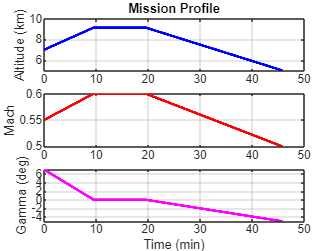


%% Mission Plot

planner.plot_mission();

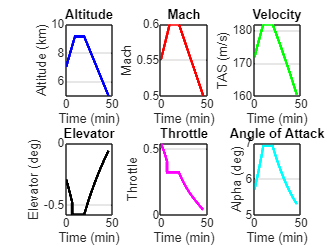


%% Trim Schedule Plot

figure('Name','Trim Schedule')
alpha_rad = atan2( mission.state_profile(6,:), mission.state_profile(4,:));
subplot(2,3,1)
plot( mission.time_vector/60, mission.altitude_profile/1000,'b', 'LineWidth',2);

grid on

xlabel('Time (min)')
ylabel('Altitude (km)')
title('Altitude')

subplot(2,3,2)

plot( mission.time_vector/60, mission.mach_profile, 'r','LineWidth',2);

grid on

xlabel('Time (min)')
ylabel('Mach')
title('Mach')

subplot(2,3,3)

plot( mission.time_vector/60,mission.velocity_profile, 'g', 'LineWidth',2);

grid on

xlabel('Time (min)')
ylabel('TAS (m/s)')
title('Velocity')

subplot(2,3,4)

plot( mission.time_vector/60, rad2deg(mission.control_profile(2,:)), 'k', 'LineWidth',2);

grid on

xlabel('Time (min)')
ylabel('Elevator (deg)')
title('Elevator')

subplot(2,3,5)

plot(mission.time_vector/60, mission.control_profile(thr_idx,:), 'm','LineWidth',2);

grid on

xlabel('Time (min)')
ylabel('Throttle')
title('Throttle')

subplot(2,3,6)

plot(  mission.time_vector/60,rad2deg(alpha_rad),'c', 'LineWidth',2);

grid on

xlabel('Time (min)')
ylabel('Alpha (deg)')
title('Angle of Attack')